assert(endsWith(pwd, "\biological block in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear

## Distributed Current Source

#### Electromagnet

Coil.num = 3;
Coil.inner_radius = [3.75e-3 3.75e-3 3.75e-3]; % (m)
Coil.outer_radius = [6.00e-3 6.00e-3 6.00e-3]; % (m)
Coil.length       = [4.00e-3 3.00e-3 3.00e-3]; % (m)

Coil.wire_diameter = [0.35e-3 0.08e-3 0.08e-3]; % (m)
Coil.N_turns = [60 1000 1000];
Coil.conductivity = 6e7 * ones(1,3); % (S/m)

Coil_z = [6.00e-3 2.00e-3 10.0e-3]; % (m)
Coil_pos = [zeros(size(Coil_z)); zeros(size(Coil_z)); Coil_z];

Coil = SetPositionRotation3D(Coil, Coil_pos);
clear Coil_z Coil_pos

#### Sensor

Sensor.num = 0;

#### Model

block.l = 60e-3; % (m)
block.h = 10e-3;  % (m)
block.n_l = 29; % number of elements in x and y direction % ensure odd number
block.n_z = 5;  % number of elements in z direction

x = linspace(-block.l/2, block.l/2, block.n_l+1);
y = x;
z = linspace(-block.h, 0, block.n_z+1);

Model = BuildModel3D('Cuboid', x,y,z);

build model took 0.11 seconds


clear block x y z

f = 50000; % (Hz)
Model.conductivity          = 0.0720427887628287 * ones(1,Model.num_elems); % (S/m)
Model.relative_permittivity = 10689.6532890173 * ones(1,Model.num_elems); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elems); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil, Sensor);

build governing equation took 36.71 seconds


#### Solve in frequency domain

Coil.frequency_domain.excitation = {"Current" 0.01; "Current" 0; "Current" 0}; % (A)

Coil.frequency_domain.frequency = f;
clear f

[Model, Coil, Sensor] = SolveFrequencyDomain3D(GoverningEquation, Model, Coil, Sensor);

solve in frequency domain took 49.48 seconds


#### Plot world

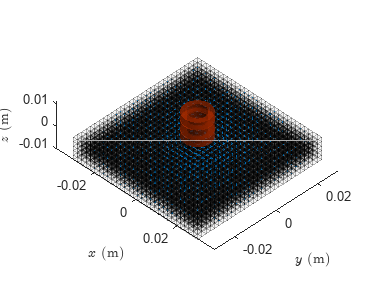

r = Model.elems_center;
J = real(Model.frequency_domain.J);

figure
PlotWorld3D(Model, Coil, Sensor);
quiver3(r(1,:),r(2,:),r(3,:), J (1,:),J (2,:),J (3,:));


clear r J

## Compare with FEA

#### Current density

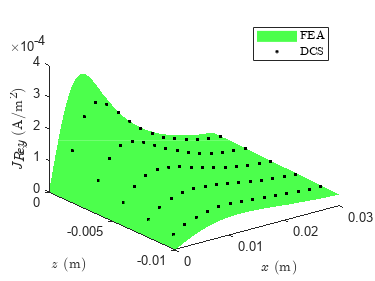

data = readmatrix('FEA_data/J.txt', 'CommentStyle','%');
FEA.x  = reshape(data(:,1), 50, []);
FEA.z  = reshape(data(:,3), 50, []);
FEA.Jy = reshape(data(:,4), 50, []);
clear data

mask = Model.elems_center(1,:) > 0 & Model.elems_center(2,:) == 0;

figure
hold on
surf(FEA.x, FEA.z, real(FEA.Jy), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
plot3(Model.elems_center(1,mask), Model.elems_center(3,mask), real(Model.frequency_domain.J(2,mask)), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Re,y}$ (A/m$^2$)", 'Interpreter','latex')
view(3)


J_FEA = interp2(FEA.x', FEA.z', real(FEA.Jy)', Model.elems_center(1,mask), Model.elems_center(3,mask));
J_DSC = real(Model.frequency_domain.J(2,mask));
error = mean(abs(J_DSC - J_FEA)) /  mean(abs(J_FEA),'all');
fprintf("relative error: %f%%", error*100)

relative error: 5.188467%

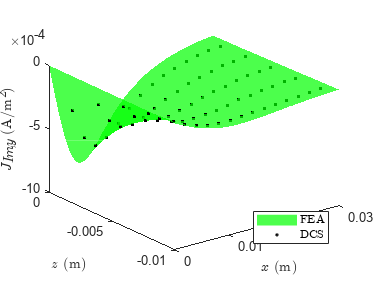


figure
hold on
surf(FEA.x, FEA.z, imag(FEA.Jy), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
plot3(Model.elems_center(1,mask), Model.elems_center(3,mask), imag(Model.frequency_domain.J(2,mask)), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Im,y}$ (A/m$^2$)", 'Interpreter','latex')
view(3)


J_FEA = interp2(FEA.x', FEA.z', imag(FEA.Jy)', Model.elems_center(1,mask), Model.elems_center(3,mask));
J_DSC = imag(Model.frequency_domain.J(2,mask));
error = mean(abs(J_DSC - J_FEA)) /  mean(abs(J_FEA),'all');
fprintf("relative error: %f%%", error*100)

relative error: 5.212858%


clear mask J_FEA J_DSC error

#### Coil voltage

FEA_V = readmatrix('FEA_data/V_E.csv', 'CommentStyle','%');
FEA_V = reshape(FEA_V(4:end), 3,2);
V_fix = (FEA_V(2,2) - FEA_V(3,2)) / 2;
FEA_V(2,:) = FEA_V(2,:) - V_fix;
FEA_V(3,1) = FEA_V(3,1) + V_fix;
FEA_V = FEA_V(:,1);

DCS_V = Coil.frequency_domain.V;

T = table([FEA_V(2);DCS_V(2)], [FEA_V(3);DCS_V(3)], [FEA_V(2)-FEA_V(3);DCS_V(2)-DCS_V(3)], 'VariableNames',["Lower coil voltage (V)","Upper coil voltage (V)","Differential voltage (V)"], 'RowNames',["FEA","DCS"]);
disp(T)

           Lower coil voltage (V)    Upper coil voltage (V)    Differential voltage (V)
           ______________________    ______________________    ________________________

    FEA     5.4136e-06+0.65509i       5.3828e-06+0.65509i       3.0811e-08+1.2192e-08i 
    DCS     4.9926e-08+0.65698i       1.9071e-08+0.65698i       3.0854e-08+1.2731e-08i 



clear V_fix FEA_V DCS_V T